# Fresnel_diffraction.m: m-file for calculating the Fresnel diffraction of a square aperture.

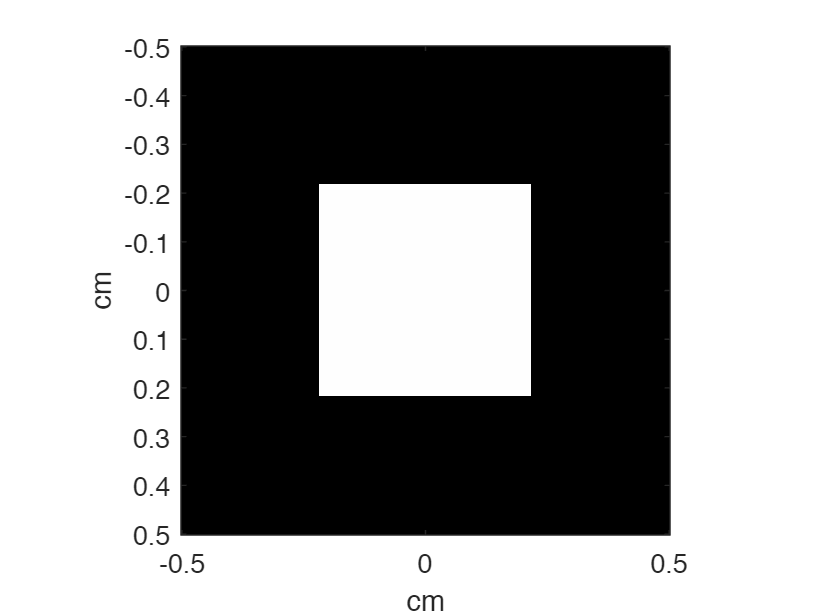

%Fresnel_diffraction.m
%Simulation of Fresnel diffraction of a square aperture
%Adapted from "Contemporary optical image processing with MATLAB®,"
%by T.-C. Poon and P. P. Banerjee, Elsevier 2001, pp. 64-65.

clc;
clear;
close all;

L=1; %L : length of display area
N=256; %N : number of sampling points
dx=L/(N-1); % dx : step size

%Create square image, M by M square, rect(x/a), M=odd number
M=111;
a=M/256;
R=zeros(256); %assign a matrix (256x256) of zeros
r=ones(M); %assign a matrix (MxM) of ones
n=(M-1)/2;
R(128-n:128+n,128-n:128+n)=r;
%End of creating input image

%Axis Scaling
for k=1:256
    X(k)=1/255*(k-1)-L/2;
    Y(k)=1/255*(k-1)-L/2; 
    
    %Kx=(2*pi*k)/((N-1)*dx) 
    %in our case, N=256, dx=1/255
    Kx(k)=(2*pi*(k-1))/((N-1)*dx)-((2*pi*(256-1))/((N-1)*dx))/2;
    Ky(k)=(2*pi*(k-1))/((N-1)*dx)-((2*pi*(256-1))/((N-1)*dx))/2; 
end 

%Fourier transformation of R

FR=(1/256)^2*fft2(R);
FR=fftshift(FR);

% Free space impulse response function 
% The constant factor exp(-jk0*z) is not calculated 
% sigma=ko/(2*z)=pi/(wavelength*z) 
% z=5cm,red light=0.6328*10^-4(cm)
sigma=pi/((0.6328*10^-4)*5); 

for r=1:256 
    for c=1:256 
        %compute free-space impulse response with Gaussian apodization against aliasing 
        h(r,c)=1i*(sigma/pi)*exp(-4*200*(X(r).^2+Y(c).^2))*exp(-1i*sigma*(X(r).^2+Y(c).^2)); 
    end
end 

H=(1/256)^2*fft2(h);
H=fftshift(H);
HR=FR.*H;
H=(1/256)^2*fft2(h);
H=fftshift(H);
HR=FR.*H;

hr=ifft2(HR);
hr=(256^2)*hr;
hr=fftshift(hr);

% Image of the rectangle object
figure(1);
image(X,Y,255*R);
colormap(gray(256));
axis square;
xlabel('cm');
ylabel('cm')

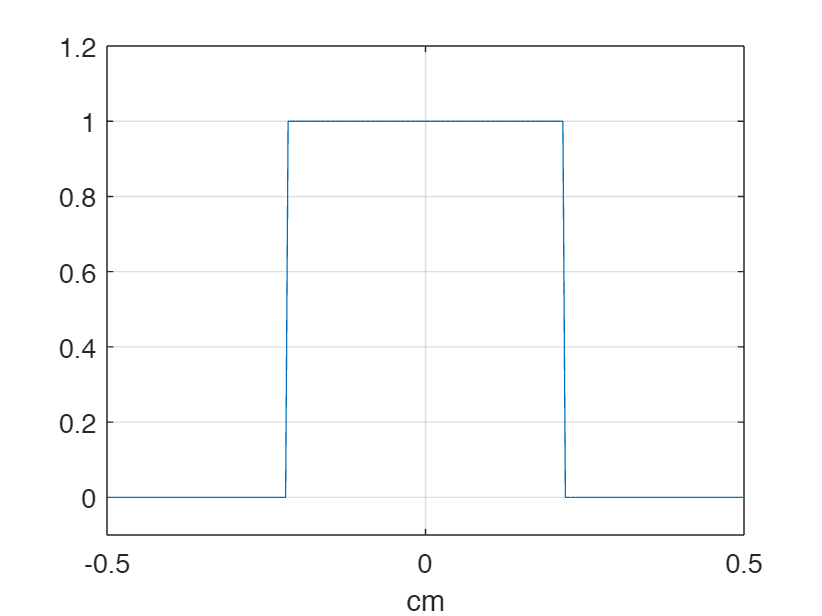


% plot of cross section of square
figure(2);
plot(X+dx/2,R(:,127));
grid;
axis([-0.5 0.5 -0.1 1.2]);
xlabel('cm');

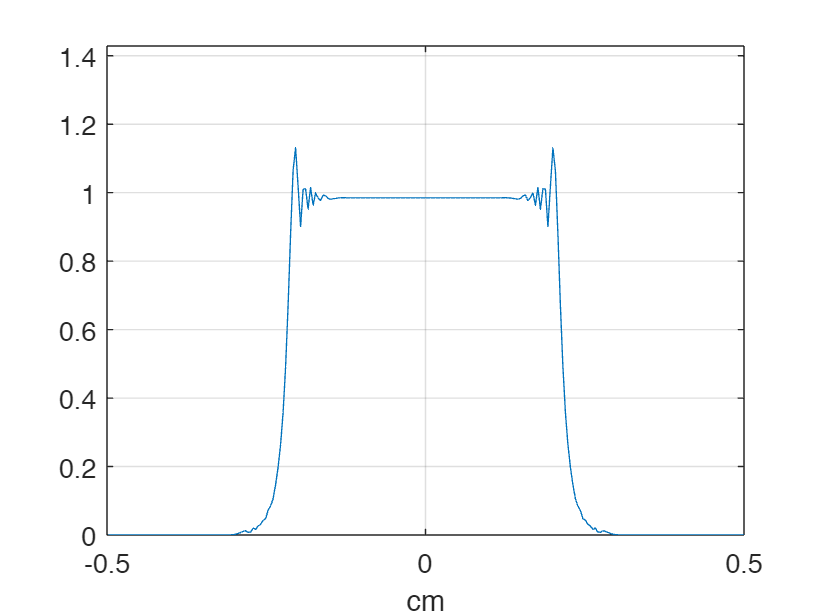


figure(3);
plot(X+dx/2,abs(hr(:,127)));
grid;
axis([-0.5 0.5 0 max(max(abs(hr)))*1.1]);
xlabel('cm');

# Fresnel_zone_plate.m: m-file for calculating FZPs illustrated in Figs. 2.19 and 2.20.

Fig. 2.19 On-axis Fresnel zone plate as a function of depth, D.

Fig. 2.20 Fresnel zone plate due to point sources at different transverse locations but otherwise located at the same depth D!.

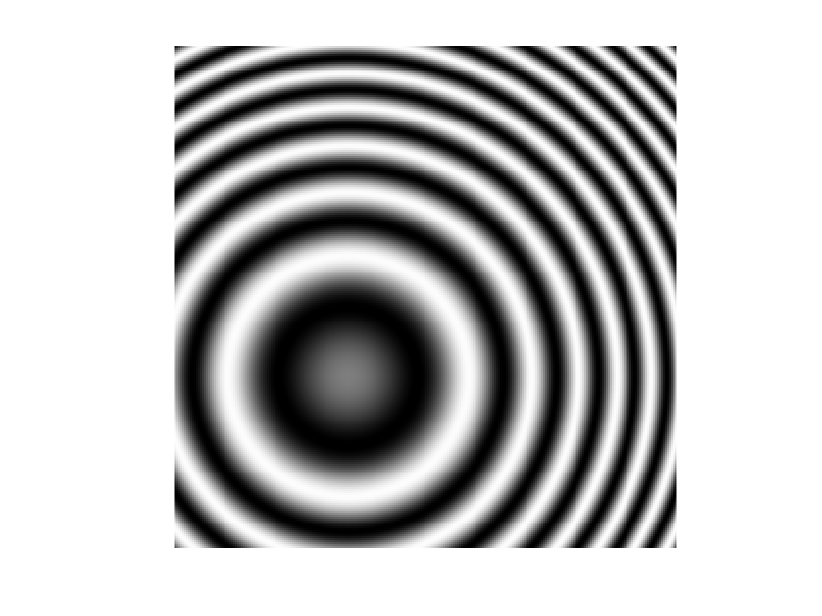

% Fresnel_zone_plate.m
% Adapted from "Contemporary optical image processing with MATLAB®,"
% by T.-C. Poon and P. P. Banerjee, Elsevier 2001, pp.177-178.
%
% display function is 1+sin(sigma*((x-x0)^2+(y-y0)^2)). All scales are arbitrary.
% sigma=pi/(wavelength*z)

clc;
clear;
close all;

z0=input ('z0, distance from the point object to film, enter z0 (from 2 to 10)=');
x0=input ('Inputting the location of the center of the FZP x0=y0,enter x0 (from -8 to 8) =');

ROWS=256;
COLS=256;
colormap(gray(255));
sigma=1/z0;
y0=-x0;
y=-12.8;

for r=1:COLS
    x=-12.8;
    for c=1:ROWS %compute Fresnel zone plate
        fFZP(r,c)=exp(1i*sigma*(x-x0)*(x-x0)+1i*sigma*(y-y0)*(y-y0));
        x=x+.1;
    end
    y=y+.1;
end

%normalization
max1=max(fFZP);
max2=max(max1);
scale=1.0/max2;
fFZP=fFZP.*scale;
R=127*(1+imag(fFZP));
figure(1);
image(R);
axis square on;
axis off